# Heuristic Tuning

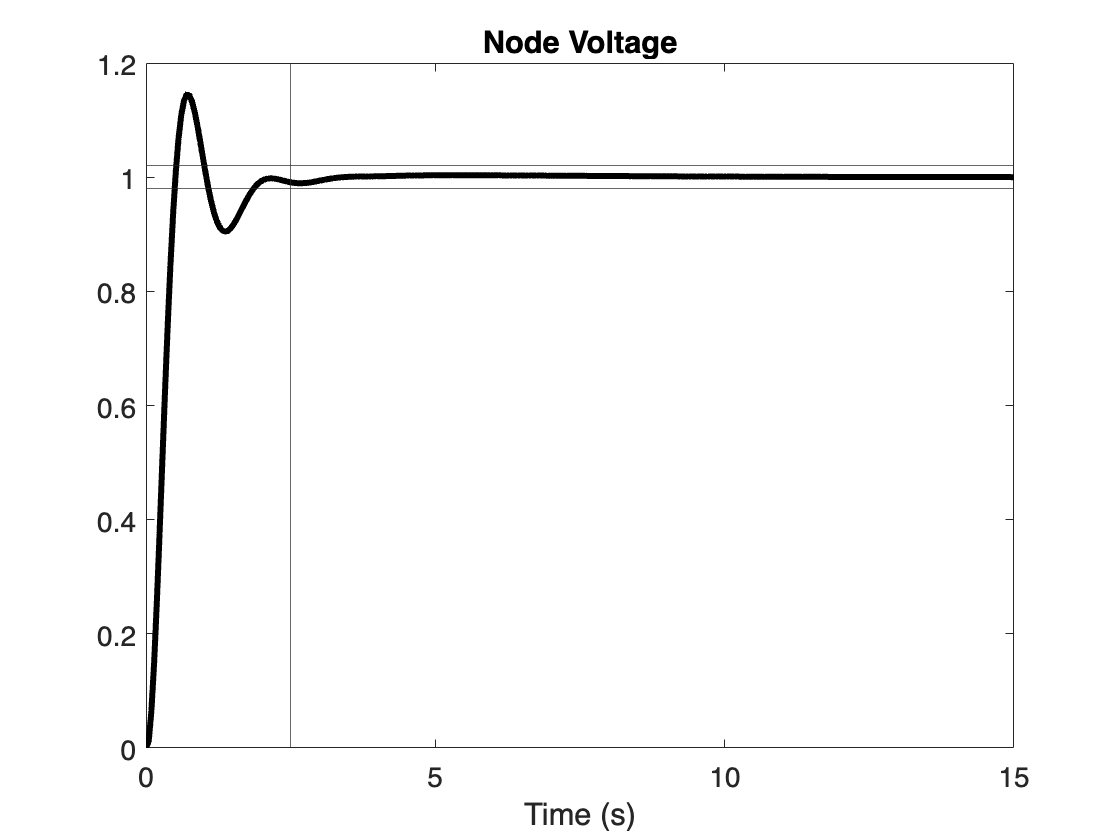

K_mod = 1;
Kp_mod = 4.28;
Ki_mod = 1.06;
Kd_mod= 100;
s = tf('s');
PID = K_mod*(Kp_mod + Ki_mod*1/s + Kd*(-p*s)/(s-p));
Gcl = feedback(PID*Gp, H);
[v_func,t_func] = step(Gcl, 15);
plot(t_func, v_func, 'k-',  'Linewidth', 3);
title('Node Voltage');
xlabel('Time (s)')
set(gca, 'FontSize', 14);
    yline(0.98);
    yline(1.02);
    xline(2.5)